# GQ 2 Modèle DCC et Granger Test

clc;
clear,
data = readtable('inefficiency.xlsx');
dates = data(:,1); % date
data = data(:,2:end); % inefficiency

varNames = data.Properties.VariableNames;

### Test d'augmented Dickey Fuller

adfLags = 9;
[adfStats, adfP] = performADFTest(data, adfLags);

adfResults = table( ...
    varNames(:), ...
    adfStats(:), ...
    adfP(:), ...
    repmat(adfLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

adfResults = 4×4 table
    MarketIndex    Statistic     pValue      Lags
    ___________    _________    _________    ____

    {'s_p500' }     -1.5493       0.11446     9  
    {'ssec'   }     -3.1599     0.0021295     9  
    {'ftse100'}     -1.9659      0.047301     9  
    {'ftsemib'}     -1.8966      0.055321     9  


## Test de présence d'effet ARCH

archResults = performARCHTest(data, 12)

archResults =   516.0163  505.4013  514.8480  515.0004



archLags = 12;
[archStats, archP] = performARCHTest(data, archLags);

archResults = table( ...
    varNames(:), ...
    archStats(:), ...
    archP(:), ...
    repmat(archLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

archResults = 4×4 table
    MarketIndex    Statistic    pValue    Lags
    ___________    _________    ______    ____

    {'s_p500' }     516.02        0        12 
    {'ssec'   }      505.4        0        12 
    {'ftse100'}     514.85        0        12 
    {'ftsemib'}        515        0        12 


## GARCH

% Supposons que "I_matrix" soit une table ou une matrice de séries
[volconds, resids] = estimateGARCH(data);

Estimation des modèles GARCH...
    {'s_p500'}    {'ssec'}    {'ftse100'}    {'ftsemib'}



## Etude de DCC

R = [data.s_p500 data.ssec];

% Dynamic conditional model without asymmetry effect
M=1;

R =     0.0425    0.0012
    0.0597   -0.0002
    0.0611   -0.0034
    0.0689   -0.0070
    0.0839   -0.0079
    0.0785   -0.0032
    0.0866    0.0089
    0.0956    0.0123
    0.0990    0.0223
    0.1070    0.0287


L=0;
N=1;
P=1;
O=0; % Mettre à 1 si présence d'un effet d'asymétrie
Q=1;

% estimation of scalar DCC
[Paramdcc,LLdcc,Htdcc,VCVdcc]=dcc(R,[],M,L,N,P,O,Q);

% covariance
cov_dcc = squeeze(Htdcc(1,2,:));


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.314745e+03    0.000e+00    1.097e+03
    1       7    1.074803e+03    0.000e+00    9.265e+03    6.265e-01
    2      10    1.030109e+03    0.000e+00    8.403e+01    5.826e-01
    3    

v_1 = squeeze(Htdcc(1,1,:));
v_2 = squeeze(Htdcc(2,2,:));
corr_dcc = cov_dcc./sqrt(v_1.*v_2);
subplot(2,1,1);
plot(cov_dcc);
title('Covariance du modèle dcc entre ');
subplot(2,1,2);
plot(corr_rm_Cns)
title('Correlation entre rm et Cnsmr')


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.314745e+03    0.000e+00    1.097e+03
    1       7    1.074803e+03    0.000e+00    9.265e+03    6.265e-01
    2      10    1.030109e+03    0.000e+00    8.403e+01    5.826e-01
    3    

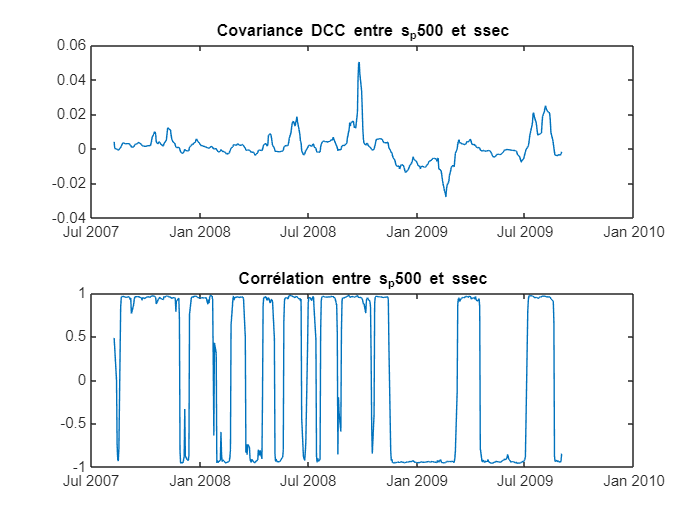


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    9.086310e+02    0.000e+00    3.803e+03
    1       9    8.199678e+02    0.000e+00    1.118e+04    1.689e-02
    2      16    9.999387e+02    0.000e+00    1.313e+03    2.041e-02
    3    

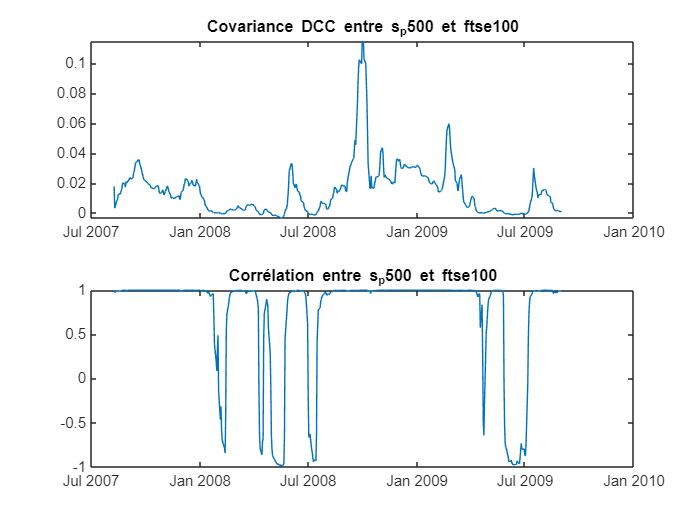


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.005546e+03    0.000e+00    3.932e+03
    1       9    9.084078e+02    0.000e+00    1.067e+04    2.018e-02
    2      16    1.110022e+03    0.000e+00    1.317e+03    2.409e-02
    3    

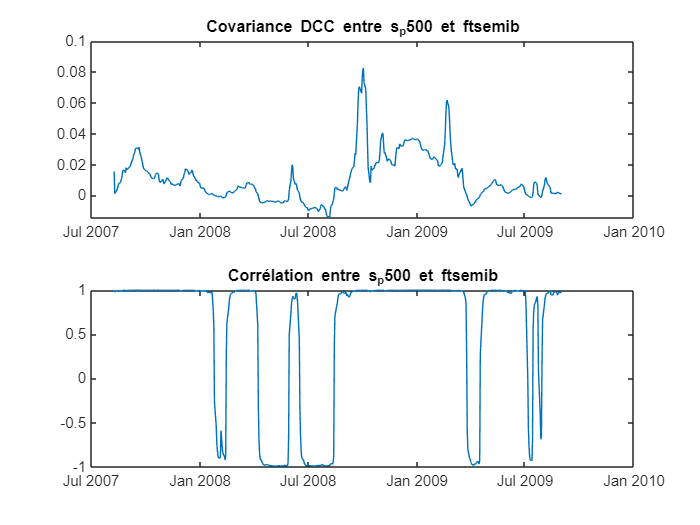


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.323918e+03    0.000e+00    8.399e+02
    1       6    1.207020e+03    0.000e+00    5.833e+02    1.076e+00
    2       9    1.164321e+03    0.000e+00    6.526e+02    7.058e-02
    3    

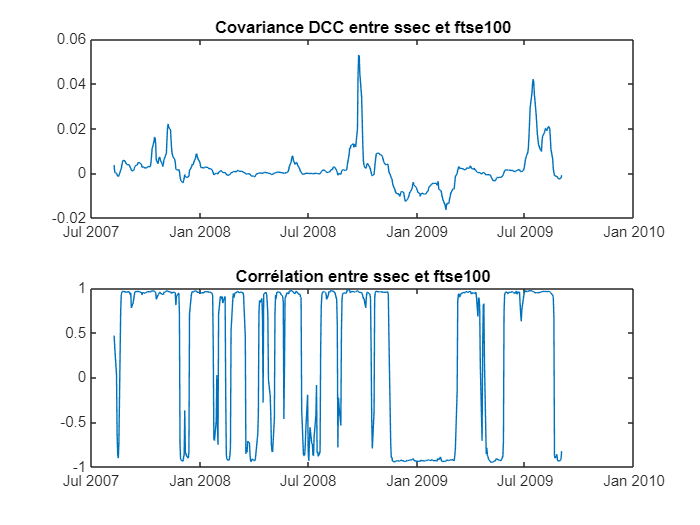


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.299794e+03    0.000e+00    1.305e+03
    1       7    1.087636e+03    0.000e+00    7.370e+03    6.265e-01
    2      10    1.058810e+03    0.000e+00    4.083e+02    5.803e-01
    3    

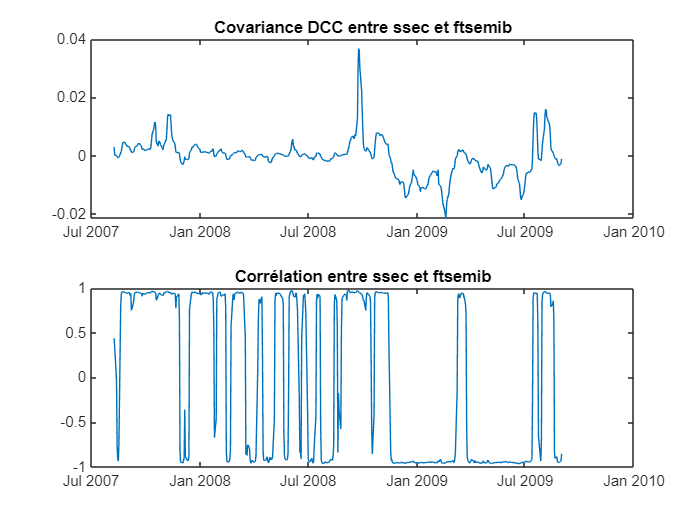


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.027054e+03    0.000e+00    3.428e+03
    1       9    9.452820e+02    0.000e+00    1.086e+04    1.720e-02
    2      16    1.111327e+03    0.000e+00    1.180e+03    2.072e-02
    3    

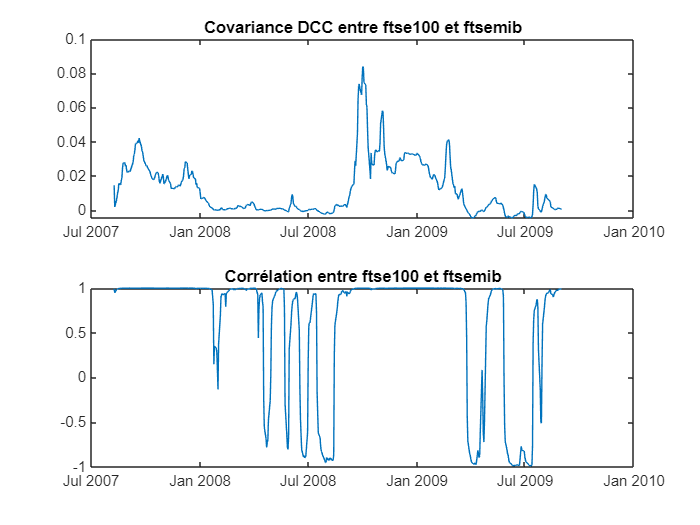

% Paramètres du modèle DCC
M = 1;
L = 0;
N = 1;
P = 1;
O = 0; % Mettre à 1 si présence d'un effet d'asymétrie
Q = 1;

for i = 1:numCols
    for j = i+1:numCols
        % Extract the pair of columns as vectors
        data1 = table2array(data(:, i));
        data2 = table2array(data(:, j));
        
        colName1 = data.Properties.VariableNames{i};
        colName2 = data.Properties.VariableNames{j};

        % Compute DCC
        [cov_dcc, corr_dcc] = computeDCC(data1, data2, M, L, N, P, O, Q);

        % Create a new figure for each pair
        figure;

        % Plot the results
        subplot(2, 1, 1);
        plot(table2array(dates), cov_dcc);
        title(['Covariance DCC entre ', colName1, ' et ', colName2]);

        subplot(2, 1, 2);
        plot(table2array(dates), corr_dcc);
        title(['Corrélation entre ', colName1, ' et ', colName2]);
    end
end

data = [0.01; -0.02; 0.03; -0.01; 0.02];  % Exemples de rendements journaliers

% Paramètres max_p et max_q
max_p = 5;
max_q = 5;

% Appeler la fonction performGARCH
[best_model, best_p, best_q] = performGARCH(data, max_p, max_q);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00012634      0.032831        0.0038483    0.99693
    GARCH{1}       0.69477        85.508        0.0081253    0.99352
    ARCH{1}          2e-12        2.8237       7.0829e-13          1



 
    GARCH(1,2) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00012634       0.10305         0.001226    0.99902
    GARCH{1}       0.69478        255.45        0.0027198    0.99783
    ARCH{1}              0         12.63                0          1
    ARCH{2}          2e-12        29.099       6.8731e-14          1



 
    GARCH(1,3) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    1.8264e-05       0.4186        4.3631e-05    0.99997
    GARCH{1}         2e-12       515.95        3.8764e-15          1
    ARCH{1}              0       566.49                 0          1
    ARCH{2}              0       10.275                 0          1
    ARCH{3}              1       1032.5        0.00096857    0.99923



 
    GARCH(2,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00012634       0.18106        0.0006978    0.99944
    GARCH{1}       0.69478        491.48        0.0014137    0.99887
    GARCH{2}         2e-12        965.69        2.071e-15          1
    ARCH{1}          2e-12        13.002       1.5382e-13          1



 
    GARCH(2,2) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00012635       0.1134         0.0011142    0.99911
    GARCH{1}       0.69477       163.38         0.0042525    0.99661
    GARCH{2}         2e-12       123.04        1.6255e-14          1
    ARCH{1}              0        12.69                 0          1
    ARCH{2}          2e-12       25.662        7.7936e-14          1




% Afficher les résultats
disp('Best Model:');
disp(best_model);
disp('Best p:');
disp(best_p);
disp('Best q:');
disp(best_q);
disp('AIC Values:');
disp(AIC_values);
disp('BIC Values:');
disp(BIC_values);
disp('Estimated Model:');
disp(est_model);